# Inverse Kinematics of Stewart Platform

### 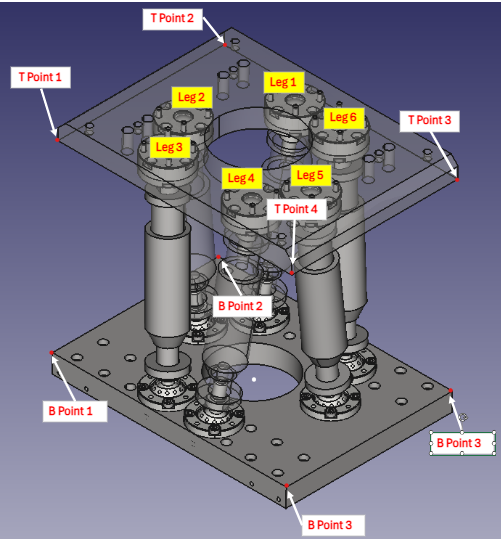

% Define the desired position and orientation of the moving platform
desired_position = [-10; 15; 185]; % Desired position [x, y, z]
desired_orientation = [10; -15; 20]*pi/180; % Desired orientation [roll, pitch, yaw] In DEGREE

R1=130/2; %radious of the base frame
R2=125/2; %radious of the moving frame
GAMMA=20; % half angle between to adjacent legs


% Define the fixed and moving platform geometry (attachment points)
% Fixed platform attachment points (in the base frame)
B1=[R1*cosd(60-GAMMA) R1*sind(60-GAMMA) 0]'; 
B2=[R1*cosd(60+GAMMA) R1*sind(60+GAMMA) 0]'; 
B3=[-R1*cosd(GAMMA) R1*sind(GAMMA) 0]'; 
B4=[-R1*cosd(GAMMA) -R1*sind(GAMMA) 0]'; 
B5=[R1*cosd(60+GAMMA) -R1*sind(60+GAMMA) 0]'; 
B6=[R1*cosd(60-GAMMA) -R1*sind(60-GAMMA) 0]'; 

B = [B1 B2 B3 B4 B5 B6];

% Moving platform attachment points (in the moving frame)
P1=[R2*cosd(GAMMA) R2*sind(GAMMA) 0]';
P2=[-R2*sind(30-GAMMA) R2*cosd(30-GAMMA) 0]';
P3=[-R2*sind(30+GAMMA) R2*cosd(30+GAMMA) 0]';
P4=[-R2*sind(30+GAMMA) -R2*cosd(30+GAMMA) 0]';
P5=[-R2*sind(30-GAMMA) -R2*cosd(30-GAMMA) 0]';
P6=[R2*cosd(GAMMA) -R2*sind(GAMMA) 0]';

P = [P1 P2 P3 P4 P5 P6];


% Solve inverse kinematics to find the lengths of each leg
leg_lengths = inverseKinematics(desired_position, desired_orientation, B, P);

Leg Lengths are:
  204.9045

  193.4926

  174.6116

  169.5686

  178.3091

  208.0538



P_rect_global =  -122.0492   27.7169  102.0492  -47.7169
   96.5349  145.1424  -66.5349 -115.1424
  168.8901  218.2097  201.1099  151.7903


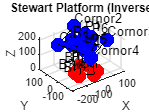


% Display the Stewart platform
[R, P_global, top_centre] = displayStewartPlatform(desired_position, desired_orientation, B, P);

# Functions

function leg_lengths = inverseKinematics(desired_position, desired_orientation, B, P)
    % Convert orientation to rotation matrix
    R = Eul2rotm(desired_orientation);

    % Calculate leg lengths
    leg_lengths = zeros(6, 1);
    disp("Leg Lengths are:")
    for i = 1:6
        % Position of attachment point on moving platform in world frame
        Pi = desired_position + R * P(:, i);
        
        % Vector from base attachment point to moving platform attachment point
        L = Pi - B(:, i);
        
        % Leg length
        leg_lengths(i) = norm(L);
        disp(leg_lengths(i))
    end

end


% Utility function to convert Euler angles to rotation matrix
function R = Eul2rotm(eul)
    % Assuming Euler angles are in the order of [roll, pitch, yaw]
    R = eul2rotm([eul(1), eul(2), eul(3)],"XYZ");
end

function [R, P_global, top_centre] = displayStewartPlatform(desired_position, desired_orientation, B, P)
    % Convert orientation to rotation matrix
    R = Eul2rotm(desired_orientation);
    P_global = desired_position + R * P;


    figure;
    hold on;
%%%%%%%%%%%%%%%%%Plotting Rectangle

    RP1 = [-82.5,112.5,0]';
    RP2 = [82.5,112.5,0]';
    RP3 = [82.5,-112.5,0]';
    RP4 = [-82.5,-112.5,0]';
    Rectangle_points = [RP1 RP2 RP3 RP4];
    P_rect_global = desired_position + R * Rectangle_points

    % Plot the Rectangular attachment points
    plot3(P_rect_global(1,:), P_rect_global(2,:), P_rect_global(3,:), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    fill3(P_rect_global(1,:), P_rect_global(2,:), P_rect_global(3,:),'b','FaceAlpha', 0.05);
    text(P_rect_global(1,:), P_rect_global(2,:), P_rect_global(3,:), {'Cornor1', 'Cornor2', 'Cornor3', 'Cornor4'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
%%%%%%%%%%%%%%%%%%%

    % Plot the base attachment points

    plot3(B(1,:), B(2,:), B(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    hold on
    fill3(B(1,:), B(2,:), B(3,:),'r', 'FaceAlpha', 0.2);
    text(B(1,:), B(2,:), B(3,:), {'B1', 'B2', 'B3', 'B4', 'B5', 'B6'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
    
    

    % Plot the platform attachment points
    plot3(P_global(1,:), P_global(2,:), P_global(3,:), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    hold on
    fill3(P_global(1,:), P_global(2,:), P_global(3,:),'b','FaceAlpha', 0.2);
    text(P_global(1,:), P_global(2,:), P_global(3,:), {'P1', 'P2', 'P3', 'P4', 'P5', 'P6'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
    
    
    % Plot the legs
    for i = 1:6
        plot3([B(1,i), P_global(1,i)], [B(2,i), P_global(2,i)], [B(3,i), P_global(3,i)], 'k-');
    end


    %Plot Centre
    top_centre = mean(P_global,2);
    plot3(top_centre(1),top_centre(2),top_centre(3),'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    
    % Plot settings
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Stewart Platform (Inverse)');
    grid on;
    axis equal;
    view(3);
    hold off;
end